nvar = 2;
fun = @Shubert2_fun;
% Creation function 'gacreationlinearfeasible' and Mutation function
% 'mutationpositivebasis' gave best result so far, with -186.7304 at
% [-0.8008, 4.8581]. Global minima is -186.730909


Single objective optimization:
2 Variable(s)

Options:
CreationFcn:       @gacreationuniformint
CrossoverFcn:      @crossovertwopoint
SelectionFcn:      @selectiontournament
MutationFcn:       @mutationadaptfeasible

                                  Best           Mean      Stall
Generation      Func-count        f(x)           f(x)    Generations
    1              100          -157.7            32.1        0
    2              147          -164.9          -1.276        0
    3              194          -164.9          -16.56        1
    4              241          -164.9          -89.52        2
    5              288          -164.9          -125.7        3
    6              335          -180.8          -158.6        0
    7              382          -183.4          -142.3        0
    8              429          -183.4          -134.6        1
    9              476          -183.4          -154.7        2
   10              523          -183.4          -177.1        3
   11   

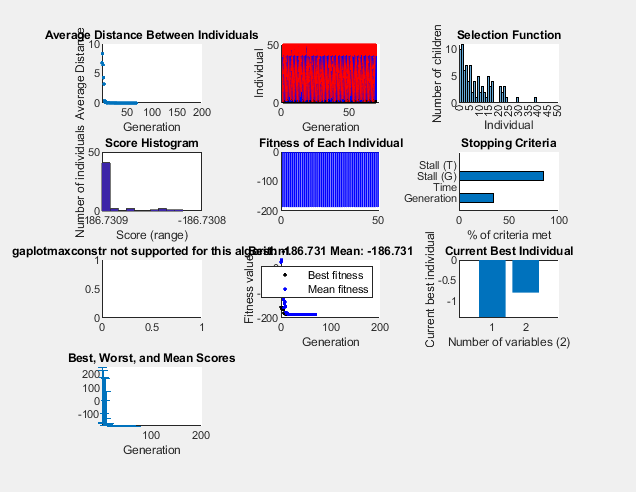

% Set nondefault solver options
options = optimoptions("ga","CrossoverFcn","crossovertwopoint",...
    "SelectionFcn","selectiontournament","PopulationSize",50,"CreationFcn",...
    "gacreationuniformint","MutationFcn","mutationadaptfeasible","Display",...
    "iter","PlotFcn",["gaplotdistance","gaplotgenealogy","gaplotselection",...
    "gaplotscorediversity","gaplotscores","gaplotstopping","gaplotmaxconstr",...
    "gaplotbestf","gaplotbestindiv","gaplotrange"]);

% Solve
[solution,objectiveValue] = ga(fun,nvar,[],[],[],[],repmat(-10,nvar,1),...
    repmat(10,nvar,1),[],[],options);


% Clear variables
clearvars options

